# Simulation-based investigation of evolutionary stability of extortionate zero-determinant strategies

## Introduction

Initialize 

Phi = 0.1;
chi = 2;
PDGame = Game([3 0;5 1]);
ExtPlayer = PlayerExtortionate(Phi,chi);
AllCPlayer = PlayerAllC;
[ExtPlayer,AllCPlayer] = PDGame.playNRounds(10000,ExtPlayer,AllCPlayer);

## Demonstration against 'AllC'-Strategy

We see that the extortionate strategy does indeed achieve a higher payoff:

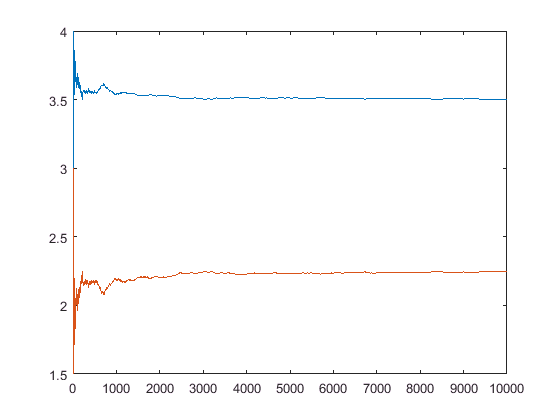

plot([ExtPlayer.AveragePayoffHistory AllCPlayer.AveragePayoffHistory])

The average payoff by the extortionate and the cooperative player as well as their ratio are given by:

[ExtPlayer.AveragePayoffHistory(end) ...

ans =     3.5026    2.2461    1.5594


    AllCPlayer.AveragePayoffHistory(end) ...
    ExtPlayer.AveragePayoffHistory(end)/AllCPlayer.AveragePayoffHistory(end)]

This compares well to the predicted values:

[(2+chi*13)/(2+chi*3) (12+3*chi)/(2+3*chi) ...

ans =     3.5000    2.2500    1.5556


    ((2+chi*13)/(2+chi*3))/((12+3*chi)/(2+3*chi))]

## Sensitivity analysis

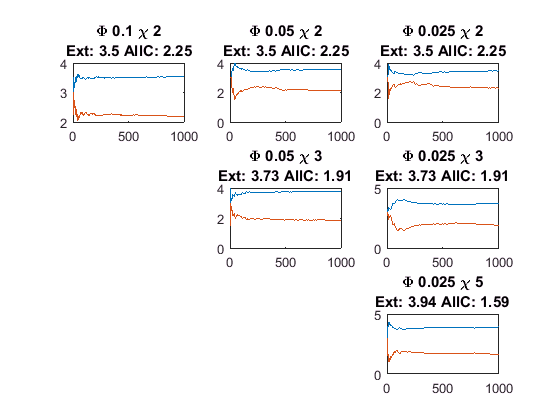

vecPhi = [0.1 0.05 0.025];
vecChi = [2 3 5];

figure 
for i = 1:9
    try
        Phi = vecPhi(mod(i-1,3)+1);
        chi = vecChi(ceil(i/3));
        
        ExtPlayer = PlayerExtortionate(Phi,chi);
        AllCPlayer = AllCPlayer.resetHistory;
        [ExtPlayer,AllCPlayer] = PDGame.playNRounds(1000,ExtPlayer,AllCPlayer);
        
        subplot(3,3,i)
        plot([ExtPlayer.AveragePayoffHistory AllCPlayer.AveragePayoffHistory])
        title(['\Phi ' num2str(Phi) ' \chi ' num2str(chi) newline 'Ext: ' ...
            num2str(round(((2+chi*13)/(2+chi*3))*100)/100) ' AllC: ' ...
            num2str(round(((12+3*chi)/(2+3*chi))*100)/100)])
    end
end